# Capítulo 01 - Lugar das Raízes

Feito pelo RUIVO - Arthur Lorencini Bergamaschi

## Relembrando sistemas

Sempre bom relembrar alguns termos de AMSD para facilitar a nossa vida ao ver sistemas malditos novamente.

FT = Função de Transferência (saída/entrada)

MA = Malha Aberta

MF = Malha Fechada

RD = Ramo Direto

LR = Lugar das Raízes

EQC = Equação Característica 

Na imagem a seguir, vemos a função de transferência

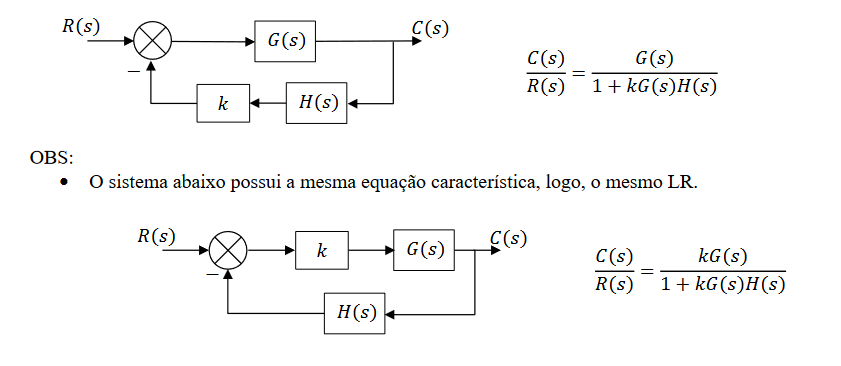

FTMF = $\frac{G\left(s\right)}{1+\mathrm{kG}\left(s\right)H\left(s\right)}$ (figura acima)

FTMA = $\mathrm{kG}\left(s\right)H\left(s\right)$ (figura abaixo)

 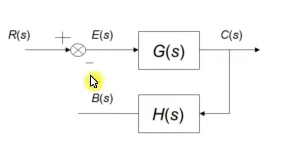

FTRD = $\mathrm{kG}\left(s\right)$ (é ignorando a realimentação totalmente)

EQC = ($1+\textrm{kG}\left(s\right)H\left(s\right)=0$)  (ou 1 + FTMA) para os dois casos. Lembre-se que é a EQC que determina a estabilidade do sistema. Portanto, os dois sistemas se comportam de maneira parecida.

## Classificação do sistema em relação a sua fase

Todo sistema que a gente estuda possui um módulo e uma fase. Dependendo de onde estão os polos e zeros, a gente pode classificar como instável, estável e marginalmente estável.

BUT, também podemos adicionar mais uma informação na classificação (baseado novamente em polos e zeros).

Temos 3 novas classificações:

Fase mínima: Quando todos os **polos e zeros** estão do lado esquerdo do eixo imaginário

Fase Máxima: Quando tiver todos os **zeros** na direita do Im.

Fase não Mínima:Quando tiver um **polo ou zero** na direita do Im.

## O (maldito) Lugar das raízes

Beleza, sabendo disso tudo, podemos nos perguntar:

*"O que diabos é o ****lugar das raízes****? É um bar? Um evento? Que porra é essa, RUIVO?"*

Se vc tem um sistema que depende de um valor variável 'k', o que aconteceria se você mapeasse todos os polos e zeros do sistema ao variar 'k' de pouquinho em pouquinho?

Não sabe? Nem eu, mas você teria um desenho que mostraria todos os polos para o K de 0 até infinito.

Vamos pegar um exemplo simples. Seja a seguinte EQC

eqc = zpk([-3,-3],[-1+j,-1-j,-2],1)

eqc =
 
        (s+3)^2
  --------------------
  (s+2) (s^2 + 2s + 2)
 
Continuous-time zero/pole/gain model.
Model Properties


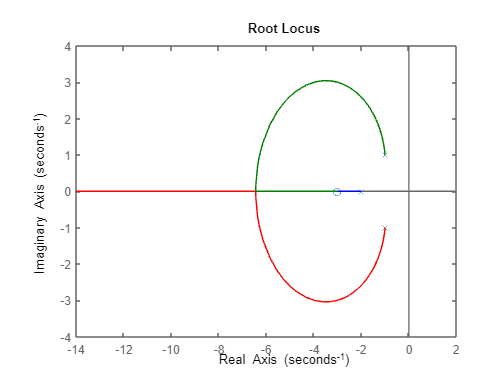

rlocus(eqc)

pole(eqc)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -2.0000 + 0.0000i


zero(eqc)

ans =     -3
    -3


Veja que a figura acima mostra os polos (x) e os zeros (o). Como temos $1+\mathrm{FTMA}=1+\frac{\mathrm{kP}\left(s\right)}{Q\left(s\right)}=0\to Q\left(s\right)+\mathrm{kP}\left(s\right)=0$, Quando k = 0, os valores de s que fazem Q(s) = 0 são os polos. ou seja, s = polos. Quando k tende ao infinito, o único jeito é fazer P(s) = 0 para satisfazer $\mathrm{kP}\left(s\right)=0$, os valores de s que fazem P(s) = 0 são os zeros, ou seja, s = zeros. É por isso que, ao aumentar o valor de k, fazemos os polos deslocarem até os zeros.

O **Lugar das raízes** é a representação gráfica dos polos e zeros do sistema quando se varia o ganho (k) de 0 a infinito. (Existe pra k negativo, mas não queremos mexer nesse vespeiro)

Vale ressaltar o seguinte: **A partir dos polos e zeros da FTMA, nós fazemos a representação gráfica da localização das raízes da EQC. **

**Além disso, vamos lidar inicialmente ****apenas**** com sistemas de fase mínima e realimentação negativa e k de 0 a infinito.**

## Condições do LR

Para um ponto fazer parte do LR, ele deve satisfazer duas condições, a de módulo e a de fase.

### Condição de fase (ou angular)

$\angle G_1 \left(s\right)H_1 \left(s\right)=180\degree \left(2n+1\right);$ Para n sendo qualquer inteiro.

### Condição de módulo

$|G_1 \left(s\right)H_1 \left(s\right)|=\frac{1}{|K|}$ ou $|{\mathrm{KG}}_1 \left(s\right)H_1 \left(s\right)|=1$

Os valores dos pontos 's' que satisfazem essas condições, são raízes da EQC, ou seja, pólos de FTMF.

Os valores de 's' que satisfzem apenas a condição angular é denominado de **LUGAR DAS RAÍZES**

Essas condições vem dessas equações aqui, caso tenha interesse (é só lembrar das definições de módulo e ângulo de número complexo:

Temos o seguinte sistema:

O módulo e fase dessa jamanta pode ser escrito dessa forma aqui: (esqueça k negativo)

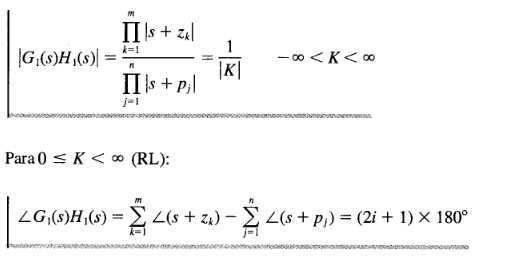

**Se você quiser testar se o ponto 'P' faz parte do LR de maneira gráfica (sem ter q lidar com polinômios macabros), você pode usar as seguintes equações:**

**O desenho mostra os polos e zeros e seus ângulos e módulos referente a um ponto de teste x.**

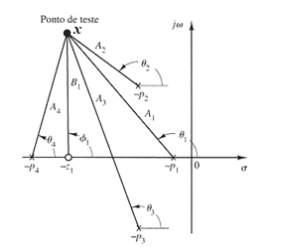

-> essa condição aqui vai se mostrar interessante para saber o valor de k no ponto x no futuro.

## Passo a Passo (resumido) para traçar o LR

O passo a passo é tão grande que parece uma maratona de tanta coisa que a gente tem que gravar.

Inicialmente vou resumir e depois explicar mais detalhadamente cada passo.

- **Representação:** $D\left(s\right)=1+\mathrm{FTMA}$

- **Reorganização:** $D\left(s\right)=1+\mathrm{kP}\left(s\right)$

- **Fatoração:** $P\left(s\right)=\frac{\Pi \left(s+z_i \right)}{\Pi \left(s+p_j \right)}$

- **Localização** - Localize os polos e zeros de P(s)

- **Segmentação** - Localize os segmentos do eixo real que fazem parte do LR

- **Separação** - Determine o número de lugares separados LS = nº de polos

- **Assíntotas** - Encontrar as informações das assíntotas

- **Cruzamento** **Real Derivado** - Encontrar pontos de saída/chegada no eixo real

- **Aproximação** - Encontrar o ângulo de saída aproximando um ponto 'x' que fica muito perto de um polo.

- **Cruzamento** **Imaginário** - Determinar o ponto de cruzamento no eixo imaginário

- **Desenhar** o LR com isso tudo

Os primeiros seis passos (EU: RUIVO) considero tranquilos, depois que começa a ir tudo pra casa do caralho. É fazer exercício até virar um reflexo automático, que nem vômito.

**Representação: **É bem simples, é só escrever a EQC.

**Reorganização:** Pode ser bem complicado, por causa de fatoração. mas essa equação vai ajudar a achar os polos e zeros no próximo passo.

**Fatoração: **Pegue a sua calculadora casio fx99 plus ou o seu matlab e ache as raízes, descreva o P(s) na forma fatorada.

**Localização:** Com essas raízes (polos e zeros), você começa a desenhar o LR.

**Segmentação: **Agora vem a maluquice (não que antes não tivesse maluquice)

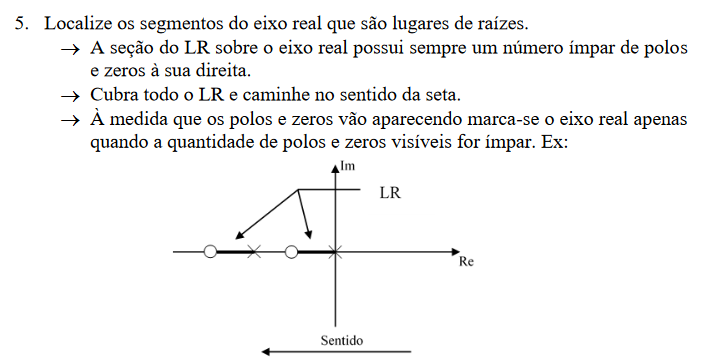

**IMPORTANTE: Cuidado com raízes múltiplas (veja quando se tem dois zeros em -3)**

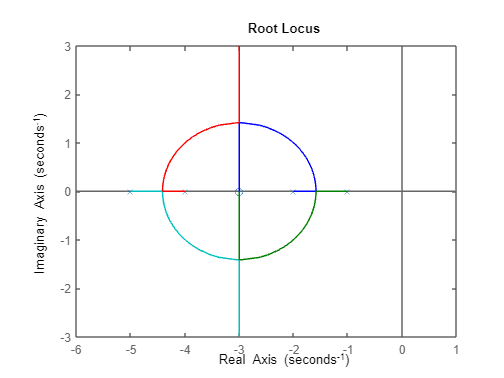

eqc_2 = zpk([-3,-3],[-1,-2,-4,-5],1);
rlocus(eqc_2)

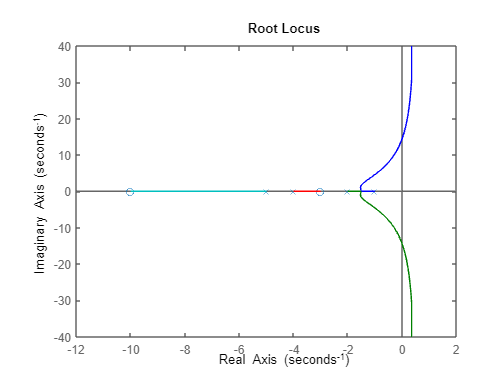

eqc_3 = zpk([-10,-3],[-1,-2,-4,-5],1);
rlocus(eqc_3)

**Separação: **Esse é trivial, basta saber o número de polos que você encontrou ao fatorar. Nº de Lugares Separados = Nº de polos. Lembre-se que todo polo procura um zero. Se tiver mais polos do que zeros, então ele vai pro infinito caçar um zero. Se tiver mais zeros do que polo (o que eu duvido muito), o polo 'vem' do infinito até o zero.

**Assíntotas:** Senta que lá vem fórmula 🍎 (ngm deve pegar essa referência do castelo rá-tim-bum).

Segue as fórmulas:


$$\mathrm{nº}\;\mathrm{assíntotas}\;\left(\mathrm{#a}\right)=\mathrm{nº}\;\mathrm{polos}-\mathrm{nº}\;\mathrm{zeros}$$
 
$$\mathrm{centroide}=\frac{\left(\sum \mathrm{polos}-\sum \mathrm{zeros}\right)}{\mathrm{#a}}$$
 
$$\mathrm{ângulos}\;\mathrm{das}\;\mathrm{assíntotas}=\theta_a =\left(2q+1\right)\frac{180º}{\mathrm{#a}}\;;q\in \left\lbrack 0,\mathrm{#a}-1\right\rbrack$$


Você pode ignorar a parte imaginária, pois elas vão sempre se cancelar.

**Cruzamento Real: **Preparem-se para fazer regra do quociente para derivadas.

(se vc quiser só saber a fórmula, pode pular essa parte)

**---- Explicação:**

Quando os polos se encontram no eixo real. quer dizer que temos um polo com multiplicadade duplicada lá. Lembre-se que esse polo duplo ele zera tanto a função, quanto a derivada dela. (ex para uma função com raíz dupla em -2:$f\left(x\right)=x^2 +4x+4={\left(x+2\right)}^{2\;} =0;f^{\prime } \left(x\right)=2x+4;f\left(x=-2\right)={\left(-2\right)}^2 +4\left(-2\right)+4=0\;\left(\mathrm{ok}\right);f^{\prime } \left(x=-2\right)=2\left(-2\right)+4=0\;\left(\mathrm{ok}\right)$)

Ou seja, para esse valor de k = k1 (não sabemos qual é, mas ele faz o LR cruzar o eixo real), temos $1+\frac{k_1 P\left(s\right)}{Q\left(s\right)}=0\to k_1 =-\frac{Q\left(s\right)}{P\left(s\right)}\ldotp$

Pela regra do quociente da derivada: $\frac{-d}{\mathrm{ds}}\left(\frac{Q\left(s\right)}{P\left(s\right)}\right)=\frac{\left(Q^{\prime } P`-{\mathrm{QP}}^{\prime } \right)}{P^2 }$. Como esse valor de k1 faz Q(s) = Q'(s) = 0, então $\frac{{\mathrm{dk}}_1 }{\mathrm{ds}}=0$

**---- Fim da explicação porca.**

O que você precisa saber é o seguinte:

$\frac{\mathrm{dk}}{\mathrm{ds}}=-\frac{d}{\mathrm{ds}}\left(\frac{Q\left(s\right)}{P\left(s\right)}\right)=0$ O sinal de - pode ser ignorado. As raízes reais dessa brincadeira são os pontos de encontro (mas devem pertencer ao passo da **Segmentação**). Se tiver duas ou mais raízes reais, ganha aquela que respeita a segmentação e tem maior módulo.

**Aproximação: Descobrir o ângulo de saída do polo.**

Você vai ter que chutar um Ponto P (ou x, ou qualquer letra que vc quiser) que é tão próximo a um pólo (ou zero) que você trata igualzin a ele.

Vai ter que ter os conceitos de trigonometria em dia pra caçar esses diabos de ângulos.

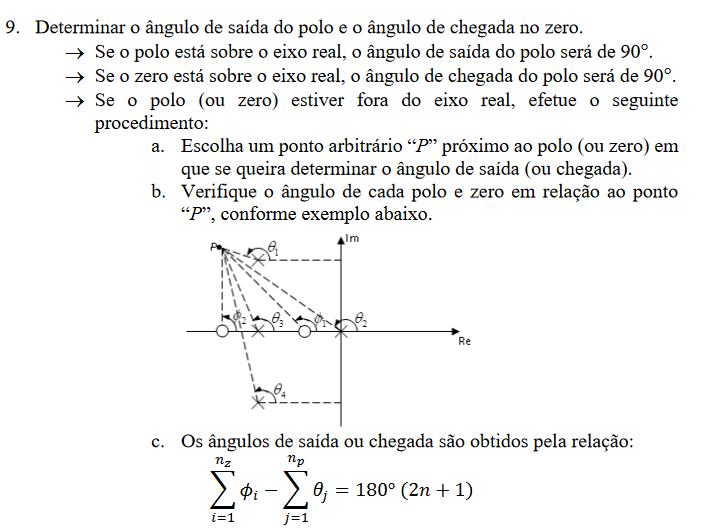

**Cruzamento imaginário: **CRITÉRIO DE ROUTH. Tava com saudades né?

Essa parte é para você saber se o LR cruza (ou não) o eixo imaginário. O critério de routh serve para saber a estabilidade do sistema, sem ter que calcular as raízes. Então vamos utilizar dele para saber o valor de k que deixa o sistema marginalmente estável. **Vou fazer um live script só contendo anotações do critério de Routh.**

Claro que, se você tiver argumentos que o LR não vai tocar em momento algum, sem utilizar o critério, então não precisa utilizar o critério. 

sys = zpk([],[0,-4,-2],2)

sys =
 
        2
  -------------
  s (s+4) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


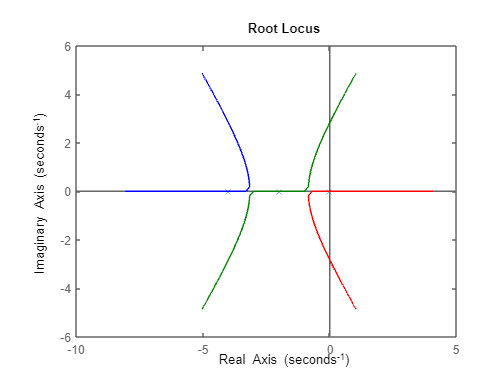

rlocus(sys,-100:.01:100)

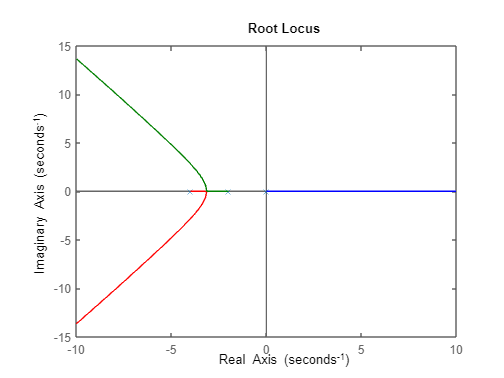

rlocus(-sys)

### Exemplos